clc;
clear all;

data = readtable("RC_Circuit_Data.xlsx");

t = data{1:end,1};
u = data{1:end,2};
y = data{1:end,3};
N = length(u)

N = 268

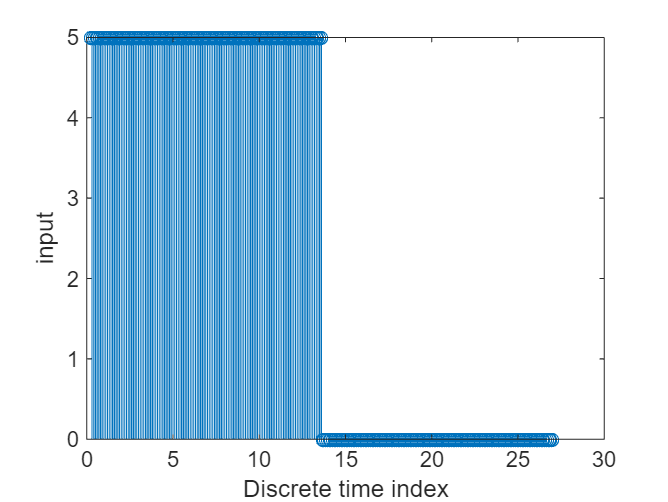

figure
stem(t,u)
xlabel('Discrete time index')
ylabel('input')

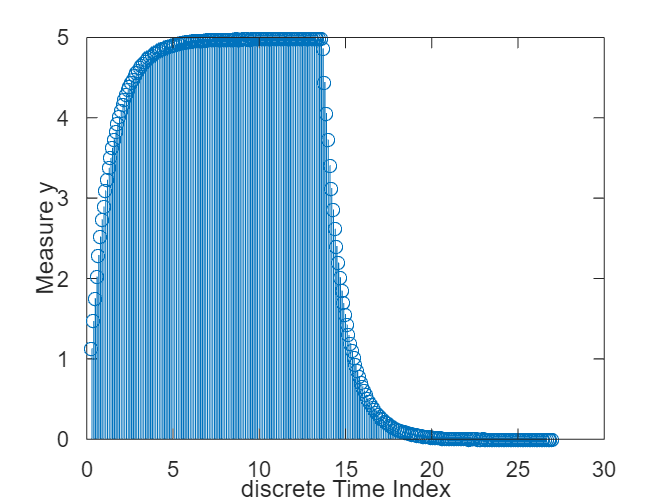

figure
stem(t,y)
xlabel('discrete Time Index')
ylabel('Measure y')

## One Step Ahead Prediction


Phi = [-y(1:N-1), u(1:N-1)];
theta_hat = Phi\y(2:N);
y_pred = Phi * theta_hat;

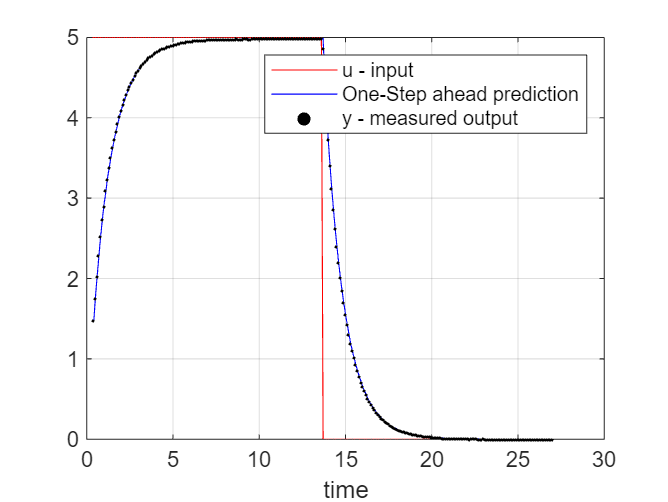

figure
plot(t,u, Color='r')
xlabel('time')
grid on
hold on
plot(t(2:N), y_pred,Color="b")
hold on
scatter(t(2:N),y(2:N),2,"black","filled","o")
legend('u - input', 'One-Step ahead prediction', 'y - measured output')
hold off

## Simulation

ysim = zeros(N,1);

for k=2:1:N
    ysim(k) = [-ysim(k-1), u(k-1)] * theta_hat;
end

figure
plot(t,u, Color='r')
xlabel('time')
grid on
hold on
plot(t, ysim,Color="b")
hold on
scatter(t,y,2,"black","filled","o")
legend('u - input', 'One-Step ahead prediction', 'y - measured output')
hold off

% %% 
% % Plot simulation results
% 
% figure
% hh=plot(t,u, t,ysim, t,y); 
% grid on; axis tight;
% title('Simulated capacitor voltage');
% legend('u - input','y_{sim} - simulated output','y - measured output');
% xlabel('Time [s]')
% 
% set(hh(1),'LineWidth',2,'Color','red','LineStyle','-');
% set(hh(2),'LineWidth',1,'Color','blue','LineStyle','-');
% set(hh(3),'LineWidth',2,'Color','black','LineStyle','none','Marker','.');